# **Cap 2 -**  **Arranjos numéricos, de células e de estruturas**  

- Podemos representar a localização de um ponto em um espaço tridimensional por meio das três coordenadas Cartesianas $x,y\;\;e\;z$

- Essas três coordenadas especificam  um vetor $\mathbf{p}$

#### EXEMPLO 1.

- **TRANSPOSIÇÃO '**

- Vetor coluna

g = [3;7;9]

g =      3
     7
     9


g' % converte vetor coluna em linha

ans =      3     7     9


- Criando vetor a partir da "anexação" de um vetor ao outro

r = [2,4,20]

r =      2     4    20


w = [9,-6,3]

w =      9    -6     3


u = [r,w]

u =      2     4    20     9    -6     3


- Operador** dois pontos (:)** facilmente gera um vetor grande de elementos regularmente espaçados

- Sintaxe: `x = m:q:n`  (se q for omitido presume-se que ele é 1)

z = 5:0.1:8

z =     5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000    6.1000    6.2000    6.3000    6.4000    6.5000    6.6000    6.7000    6.8000    6.9000    7.0000    7.1000    7.2000    7.3000    7.4000    7.5000    7.6000    7.7000    7.8000    7.9000    8.0000


r = 5:8 % x = m:n

r =      5     6     7     8


- O incremento `q `pode ser negativo. Nesse caso, `m `deve ser maior do que `n` 

u = 10:-2:4

u =     10     8     6     4


#### EXEMPLO 2.

- `linspace`

- Também cria um **vetor** linha com espaçamento** linear**

- Sintaxe `linspace(x1,x2,n)` -  `x1 `e `x2 `são os limites inferior e superior e  `n `é o número de pontos. 

 linspace(5,8,31)

ans =     5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000    6.1000    6.2000    6.3000    6.4000    6.5000    6.6000    6.7000    6.8000    6.9000    7.0000    7.1000    7.2000    7.3000    7.4000    7.5000    7.6000    7.7000    7.8000    7.9000    8.0000


#### EXEMPLO 3.

- `logspace (ver help matlab)`

- Cria um **arranjo de elementos espaçados logaritmicamente**.  

- Sintaxe: `logspace(a,b,n) -`em que `n `é o número de pontos entre ${10}^a$ e ${10}^b$  

- Se `n `for omitido, o número de pontos padrão é 50 .

x = logspace(-1,1,4)

x =     0.1000    0.4642    2.1544   10.0000


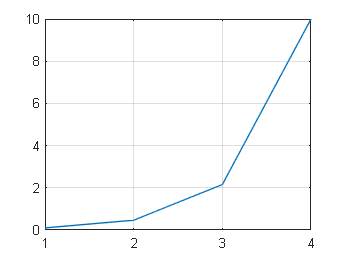

plot(x), grid on

#### EXEMPLO 4.

- **Arranjos bidimensionais**  


$$M=\left\lbrack \begin{array}{cc}
2 & 5\\
-3 & 4\\
-7 & 1
\end{array}\right\rbrack$$


- Criando matrizes :

m = [2,5;-3,4;-7,1]

m =      2     5
    -3     4
    -7     1


#### EXEMPLO 5.

- **Matrizes e a operação de transposição**


$$A=\left\lbrack \begin{array}{cc}
-2 & 6\\
-3 & 5
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;A^T =\left\lbrack \begin{array}{cc}
-2 & -3\\
6 & 5
\end{array}\right\rbrack$$


- Note que a operação de transposição converte um vetor linha em um vetor coluna, e vice-versa. 

a = [-2,6;-3,5]

a =     -2     6
    -3     5


a' %transposta de a

ans =     -2    -3
     6     5




b =  [1-2i,6;-3,2+5i]

b =    1.0000 - 2.0000i   6.0000 + 0.0000i
  -3.0000 + 0.0000i   2.0000 + 5.0000i


b'

ans =    1.0000 + 2.0000i  -3.0000 + 0.0000i
   6.0000 + 0.0000i   2.0000 - 5.0000i


#### EXEMPLO 6.

- **Endereçamento de arranjos** 

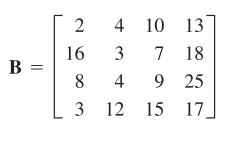

- Você pode utilizar índices de arranjo para extrair um arranjo menor a partir de outro arranjo.   

B = [2,4,10,13;16,3,7,18;8,4,9,25;3,12,15,17]

B =      2     4    10    13
    16     3     7    18
     8     4     9    25
     3    12    15    17



C = B(2:3,1:3)

C =     16     3     7
     8     4     9


#### EXEMPLO 7.

- **Arranjo Vazio**

- O *arranjo vazio *não contém nenhum elemento e é expresso como `[]` 

-  Linha e colunas podem ser deletadas igualando-se a linha ou a coluna selecionada ao arranjo vazio.  

- Por exemplo, `A(3,:) = [] `deleta a terceira coluna em `A` 

- `A(:,2:4) = [] `deleta a segunda, a terceira e a quarta coluna em `A`.

- `A([1 4],:) = [] `deleta a primeira e a quarta linha de `A`  

A = [6,9,4;1,5,7]

A =      6     9     4
     1     5     7


A(1,5) = 3 % Acrescenta número 3 na linha 1 coluna 5

A =      6     9     4     0     3
     1     5     7     0     0



B = [2,4,10,13;16,3,7,18;8,4,9,25;3,12,15,17]

B =      2     4    10    13
    16     3     7    18
     8     4     9    25
     3    12    15    17



B(1,:) = [] % Deleta a primeira linha

B =     16     3     7    18
     8     4     9    25
     3    12    15    17



B(:,2:4) = [] % deleta da segunda a quarta coluna

B =     16
     8
     3



C = [2,4,10,13;16,3,7,18;8,4,9,25;3,12,15,17]

C =      2     4    10    13
    16     3     7    18
     8     4     9    25
     3    12    15    17



C([1 4],:) = [] %deleta a primeira e a quarta linha de A

C =     16     3     7    18
     8     4     9    25


C(1,:) = 9 % Primeira linha em c recebe o valor 

C =      9     9     9     9
     8     4     9    25


C(end,:) = 99 % Ultima linha em c

C =      9     9     9     9
    99    99    99    99


C(1,4) = 1000 %Atribui um valor especifico a um unico elemento da matriz

C =            9           9           9        1000
          99          99          99          99


- Invertendo ordem de colunas de uma matriz

- O MATLAB não aceita índices negativos ou iguais a zero, mas você pode utilizar incrementos negativos com o operador dois pontos.  

A = [3,0,4,9,6;0,0,7,5,1]

A =      3     0     4     9     6
     0     0     7     5     1


B = A( :,5:-1:1) % -1:1 que realiza a inversão de todas as colunas

B =      6     9     4     0     3
     1     5     7     0     0
